# 需求分析：Legend 显示问题

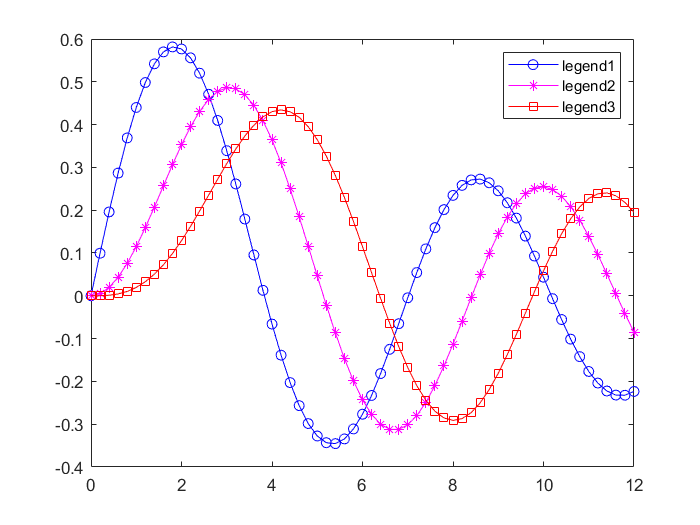

clear;clc;
% 生成曲线数据
x = 0:0.2:12;
y1 = besselj(1, x);
y2 = besselj(2, x);
y3 = besselj(3, x);
% 先看正常绘图时的 legend，显示出来的线型、标记、颜色和曲线是对应的
figure
plot(x, y1, '-ob');
hold on
plot(x, y2, '-*m');
plot(x, y3, '-sr');
hold off
legend('legend1', 'legend2', 'legend3');

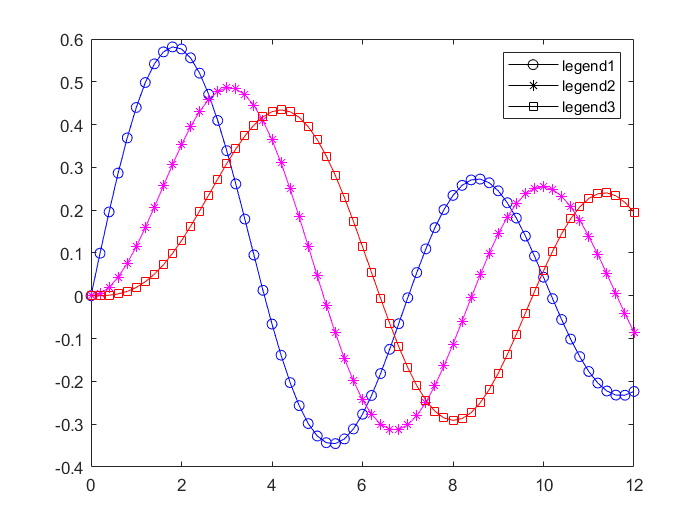

% 如果要让图例颜色都是黑色怎么实现
% 一个很笨但有效的方法，重新绘制一遍将原图覆盖
figure
plot(x, y1, '-ok');
hold on 
plot(x, y2, '-*k');
plot(x, y3, '-sk');
plot(x, y1, '-ob');
plot(x, y2, '-*m');
plot(x, y3, '-sr');
hold off
% 只显示前面三条曲线的legend
legend('legend1', 'legend2', 'legend3');

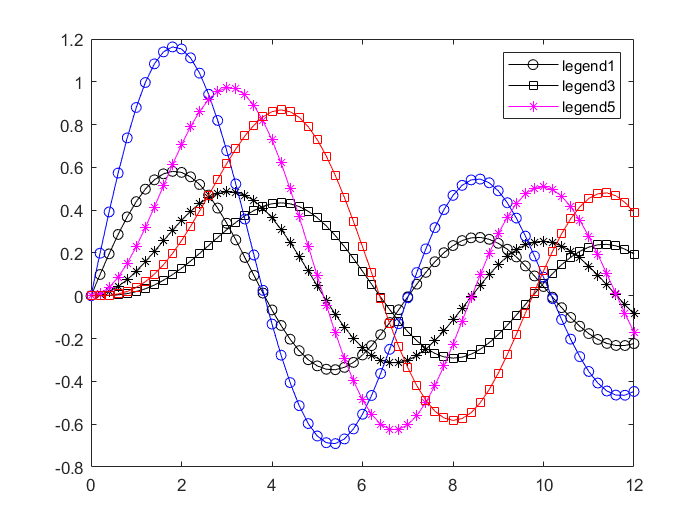

% 如果想显示指定曲线的legend
figure
h1 = plot(x, y1, '-ok');
hold on 
h2 = plot(x, y2, '-*k');
h3 = plot(x, y3, '-sk');
h4 = plot(x, 2*y1, '-ob');
h5 = plot(x, 2*y2, '-*m');
h6 = plot(x, 2*y3, '-sr');
hold off
legend([h1, h3, h5], 'legend1', 'legend3', 'legend5');